# **WMC LAB 1 **

## **Name: Rahil Sharma**

### **PRN: 18070123062**

## **Batch: G2;EA-3**

**Aim: Implementation of Amplitude Shift Keying and Frequency Shift Keying**

**Software used: MATLAB**

**Theory:**

- Amplitude Shift Keying: Amplitude Shift Keying ASKASK is a type of Amplitude Modulation which represents the binary data in the form of variations in the amplitude of a signal. Any modulated signal has a high frequency carrier. The binary signal when ASK modulated, gives a zero value for Low input while it gives the carrier output for High input.

- Frequency Shift Keying: Frequency Shift Keying FSKFSK is the digital modulation technique in which the frequency of the carrier signal varies according to the digital signal changes. FSK is a scheme of frequency modulation.The output of a FSK modulated wave is high in frequency for a binary High input and is low in frequency for a binary Low input. The binary 1s and 0s are called Mark and Space frequencies.

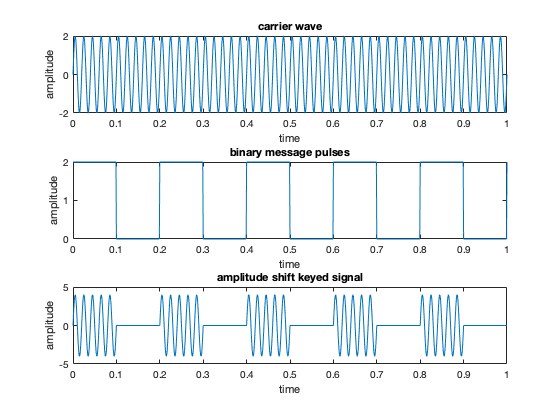

%Code for ASK
clc
close all
clear all
fc=input('enter the freq of sine wave carrier: ');
fp=input('enter the freq of periodic binary pulse: ');
amp=input('enter the amplitude: ');
t=0:0.001:1;
c=amp.*sin(2*pi*fc*t);
subplot(3,1,1)
plot(t,c)
xlabel('time')
ylabel('amplitude')
title('carrier wave')
m=amp/2.*square(2*pi*fp*t)+(amp/2);
subplot(3,1,2)
plot(t,m)
xlabel('time')
ylabel('amplitude')
title('binary message pulses')
w=c.*m;
subplot(3,1,3)
plot(t,w)
xlabel('time')
ylabel('amplitude')
title('amplitude shift keyed signal')

OUTPUTS:

Outputs 1:

- Frequency of sine wave carrier: 100

- Frequency of Periodic Binary Pulse: 10

- Amplitude: 2

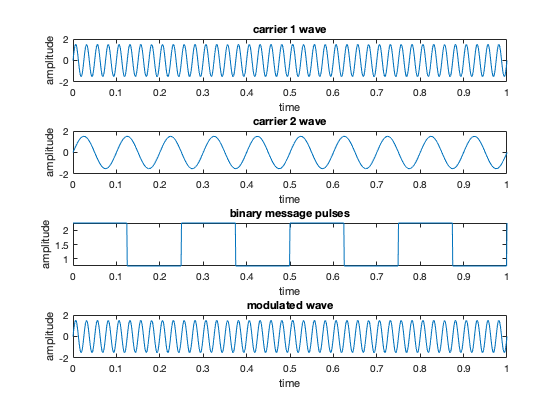

%Code for FSK
clc
close all
clear all
fc1=input('enter the freq of 1st sine wave carrier: ');
fc2=input('enter the freq of 2nd sine wave carrier: ');
fp=input('enter the freq of periodic binary pulse(message): ');
amp=input('enter the amplitude (for both carrier and binary pulse message): ');
amp=amp/2;
t=0:0.001:1;
c1=amp.*sin(2*pi*fc1*t);
c2=amp.*sin(2*pi*fc2*t);
subplot(4,1,1)
plot(t,c1)
xlabel('time')
ylabel('amplitude')
title('carrier 1 wave')
subplot(4,1,2)
plot(t,c2)
xlabel('time')
ylabel('amplitude')
title('carrier 2 wave')
m=amp/2.*square(2*pi*fp*t)+amp;
subplot(4,1,3)
plot(t,m)
xlabel('time')
ylabel('amplitude')
title('binary message pulses')
for i=0:1000
if m(i+1)==0
mm(i+1)=c2(i+1);
else
mm(i+1)=c1(i+1);
end
end
subplot(4,1,4)
plot(t,mm)
xlabel('time')
ylabel('amplitude')
title('modulated wave')

OUTPUTS: 

OUTPUT 1:

- Frequency of first sine wave carrier: 100

- Frequency of second wave carrier: 50

- Frequency of periodic binary pulse: 10

- Amplitude: 2